## Plots of gaze change per object

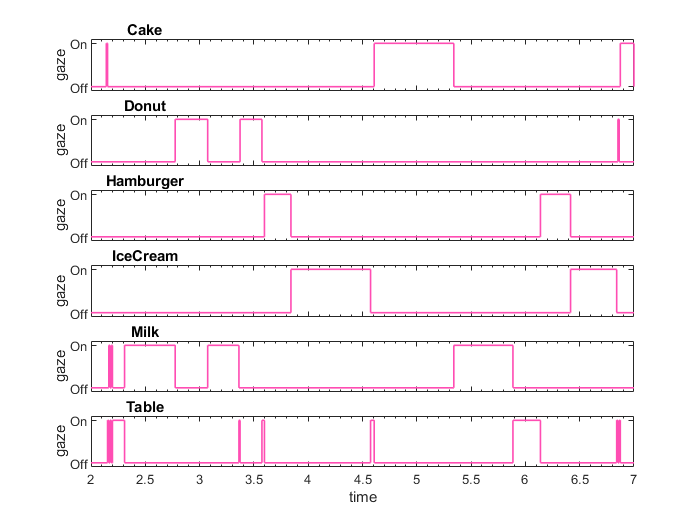

warning('off', 'all')
fc_full = readtable('Gaze_Data.csv');
warning('on', 'all')
objectIDManual = {'Table','Sphere','Cube','Cylinder','Capsule'};
objectIDs = unique(fc_full.Object);
minx = floor(min(fc_full.Time));
maxx = ceil(max(fc_full.Time));
tiledlayout(length(objectIDs),1);
time = [minx; fc_full.Time;maxx];
for i = 1:length(objectIDs)-1
    %temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);
    tempFocus = strcmp(fc_full.Object,objectIDs(i,1));
    tempFocus = [0;tempFocus;0];
    nexttile
    stairs(time, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])     
    set(gca, "XLabel",[],'XTickLabel',[],'XMinorTick',"on",'XLim',[minx maxx],...
        "ytick",[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
    ylabel('gaze')
    title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])    
end
i = length(objectIDs);
temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);    
tempFocus = strcmp(fc_full.Object,objectIDs(i,1));
tempFocus = [0;tempFocus;0];
nexttile
stairs(time, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])
set(gca, 'XMinorTick',"on",'XLim',[minx maxx],...
    'Ytick',[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
xlabel('time')
ylabel('gaze')
title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])
hold off

## fixation calculations

fixationThreshold = 0.1; %100 ms fixation threshold
totalTime = fc_full.Time(length(fc_full.Time)) - fc_full.Time(1); % might want to set this to fixed viewing time
%create new table for fixation data by each fixation, without collision
%point coordinates, with centroid coordinates, and with extra column for number of gaze
%points per fixation
fixationData = [fc_full array2table(zeros(height(fc_full),1))];  

%set first row to empty
fixationData(1,[1]).(1) = 0;
fixationData(1,[2]).(1) = cell(1,1);
fixationData(1,[3:width(fixationData)-1]) = array2table(zeros(1,(width(fixationData)-3)));

tempStartTime = fc_full.Time(1); %variable start time to calculate fixation duration 
for i = 2:height(fc_full) %iterate from second gaze point onwards
    if strcmp(fc_full.Object(i), fc_full.Object(i-1))==false % if object is different from previous gaze point
        %populate row with fixation duration and details of object
        fixationData(i,[1]).(1) = fc_full.Time(i) - tempStartTime; 
        fixationData(i,[2]).(1) = fc_full.Object(i-1);
        fixationData(i,[3:8]) = fc_full(i-1, [3:8]);
        fixationData(i,[9]) = num2cell(mean(fc_full.ColX(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i,[10]) = num2cell(mean(fc_full.ColY(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i,[11]) = num2cell(mean(fc_full.ColZ(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i,[12]) = num2cell(size(fc_full.ColZ(find(tempStartTime==fc_full.Time):i-1),1));
        tempStartTime = fc_full.Time(i); %set new start of fixation
    else
        %otherwise, populate rows as empty
        fixationData(i,[1]).(1) = 0; %put fixation time in that row for FixationData
        fixationData(i,[2]).(1) = cell(1,1);
        fixationData(1,[3:width(fixationData)-1]) = array2table(zeros(1,(width(fixationData)-3)));
    end
end
%set variable names and apply threshold of over 100ms
fixationData.Properties.VariableNames([1 9:12]) = ...
    {'Fix. Duration', 'CentrX','CentrY','CentrZ','No. Gaze Pts'};
fixationData = fixationData(fixationData.("Fix. Duration")>fixationThreshold,:);

%create new table with higher-level fixation variable data
fixVariableNames = {'Fixation Count', 'Av. Fix. Duration', ...
    'Total Fix. Duration','Proportion of fixations', 'Proportion of fix. duration'};
fixationVariables = zeros(length(fixVariableNames),length(objectIDs));
for i = 1: length(objectIDs) %iterate per object
    temp = fixationData(strcmp(fixationData.Object,objectIDs(i,1)),:);
    fixationVariables(1,i) = size(temp,1); % fixation Count
    fixationVariables(2,i) = mean(temp.("Fix. Duration")); % mean fixation duration
    fixationVariables(3,i) = sum (temp.("Fix. Duration")); % total fixation duration     
end
%proportional calculations
for i = 1:length(objectIDs)
    fixationVariables(4,i) = fixationVariables(1,i)/...
        sum(fixationVariables(1,:)); % proportion of number of fixations to total number
    fixationVariables(5,i) = fixationVariables(3,i)/...
        totalTime; %proportion of duration of fixations to total time
end
% final touches to table and display
fixationVariables = array2table(fixationVariables);
fixationVariables.Properties.VariableNames = objectIDs;
fixationVariables.Properties.RowNames = fixVariableNames;
fixationVariables

fixationVariables = 5×6 table
                                     Cake       Donut     Hamburger    IceCream     Milk       Table  
                                   ________    _______    _________    ________    _______    ________

    Fixation Count                        1          2           2           2           3           2
    Av. Fix. Duration               0.73323    0.25071     0.26096     0.57909     0.43244     0.18191
    Total Fix. Duration             0.73323    0.50141     0.52192      1.1582      1.2973     0.36383
    Proportion of fixations        0.083333    0.16667     0.16667     0.16667        0.25     0.16667
    Proportion of fix. duration     0.15174    0.10377     0.1

## Object details

tableDiameter = 0.8;
tableX = unique(fc_full.PosX(strcmp(fc_full.Object, "Table")));
tableX = tableX(1,1);
tableZ = unique(fc_full.PosZ(strcmp(fc_full.Object, "Table")));
tableZ = tableZ(1,1);
%tableX = 0.0830; %X-centre of table for offsetting
%tableZ = 0.7171; %Z-centre of table for offsetting



## Plots

Gaze points

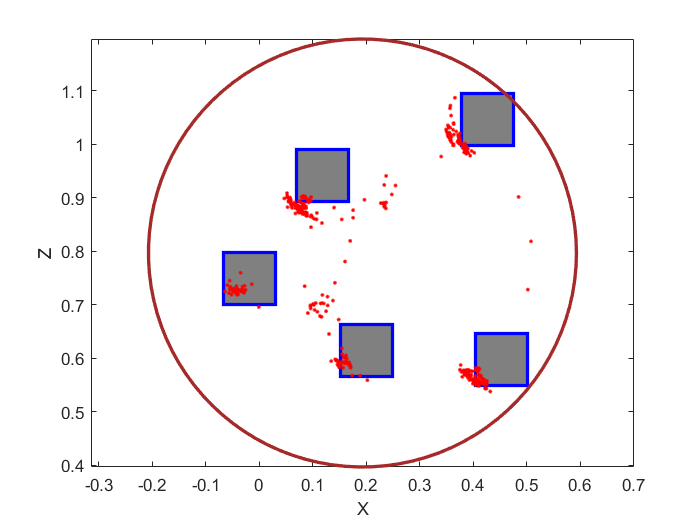

notTableL = ~(strcmp(fixationData.Object,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on
plot(fc_full.ColX, fc_full.ColZ,'.r')
hold on

% plot centroid of fixations based on gaze points (not centroid of fixations per ROI) 
% for k=1:numel(fixationData.("No. Gaze Pts"))
%   plot(fixationData.CentrX(k),fixationData.CentrZ(k),'ro',...
%       'MarkerSize',fixationData.("No. Gaze Pts")(k)/1.5,...
%       'LineWidth',1.5)
%   hold on
% %   if k+1 <= length(fixationData.CentrX)
% %     arrow3([fixationData.CentrX(k) fixationData.CentrZ(k)],...
% %       [fixationData.CentrX(k+1) fixationData.CentrZ(k+1)],'r--')
% %   end
% end
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')
hold off
axis equal

fixations proportional to number of gaze points/duration

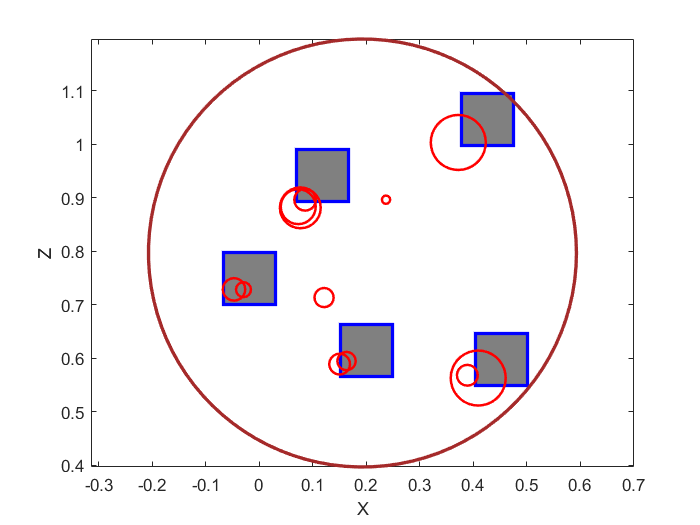

notTableL = ~(strcmp(fixationData.Object,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on

for k=1:numel(fixationData.("No. Gaze Pts"))
  plot(fixationData.CentrX(k),fixationData.CentrZ(k),'ro',...
      'MarkerSize',fixationData.("No. Gaze Pts")(k)/2,...
      'LineWidth',1.5)
  hold on
end
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')
hold off
axis equal

fixation markers proportional to fixations per object, vector markers between fixation markers

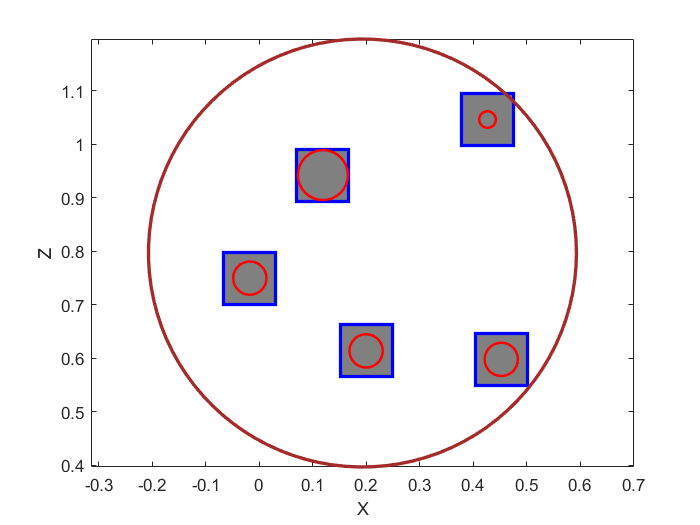

notTableL = ~(strcmp(fixationData.Object,"Table"));
notTableLObjID = ~(strcmp(objectIDs,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
%plot scanpath between fixations

theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')

%plot fixation markers proportional to number of fixations per object
for i = 1: length(objectIDs(notTableLObjID)) %iterate per object  
    temp = fixationData(strcmp(fixationData.Object,objectIDs(i,1)),:);
    for j = 1:height(temp)
        plot(temp.PosX(j),temp.PosZ(j),'ro',...
      'MarkerSize',fixationVariables.(i)(1)*10,...
      'LineWidth',1.5)
        hold on       
    end
end
% for k=1:height(fixationData)
%     if k+1 <= height(fixationData) && fixationData.PosX(k) ~= fixationData.PosX(k+1)
%             arrow3([fixationData.CentrX(k) fixationData.CentrZ(k)],...
%             [fixationData.CentrX(k+1) fixationData.CentrZ(k+1)],'r--')
%     end
% end
axis equal

notTableL = ~(strcmp(fixationData.Object,"Table"));
notTableLObjID = ~(strcmp(objectIDs,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
%plot scanpath between fixations

theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')

%plot fixation markers proportional to number of fixations per object
% for i = 1: length(objectIDs(notTableLObjID)) %iterate per object  
%     temp = fixationData(strcmp(fixationData.Object,objectIDs(i,1)),:);
%     for j = 1:height(temp)
%         plot(temp.PosX(j),temp.PosZ(j),'ro',...
%       'MarkerSize',fixationVariables.(i)(1)*10,...
%       'LineWidth',1.5)
%         hold on       
%     end
% end
for k=1:height(fixationData)
    if k+1 <= height(fixationData) && fixationData.PosX(k) ~= fixationData.PosX(k+1)
            arrow3([fixationData.CentrX(k) fixationData.CentrZ(k)],...
            [fixationData.CentrX(k+1) fixationData.CentrZ(k+1)],'r--')
    end
end

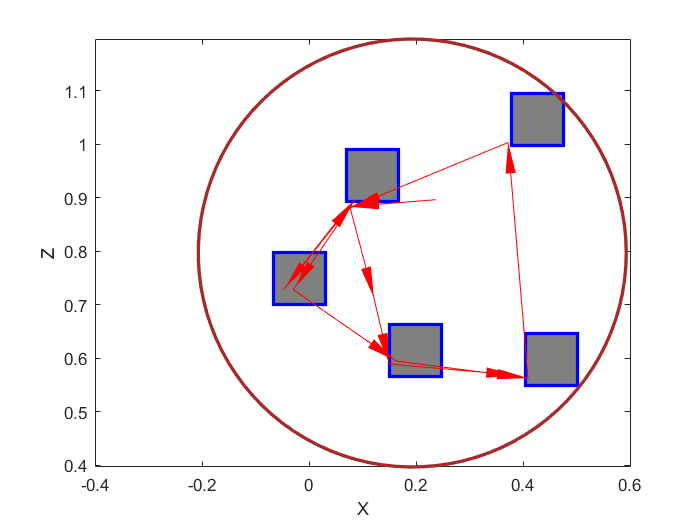

axis equal